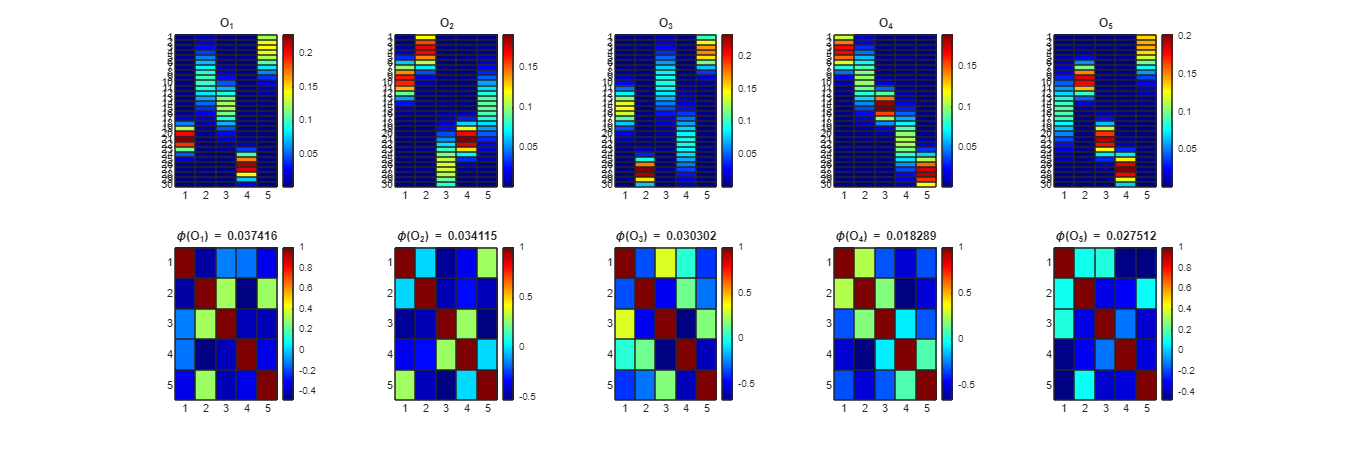

% Jep Brinkmann Thesis HMM example
clc; close all;
k = 5;
d = 30;
n = 5;

options.method = "random";
options.lambda = 5;

[T, O, pi, k, d] = generateHMM(k, d, n, options);

cost = cell(n, 1);


figure('Renderer', 'painters', 'Position', [0 0 3000 1000])

for i = 1:n
    cost{i} = sum(corrcoef(O{i}), "all")/(k*k);

    subplot(2, n, i);
    h = heatmap(O{i}, Colormap=jet());
    h.Title = ['O_' num2str(i)];

    subplot(2, n, i+n);
    h = heatmap(corrcoef(O{i}), Colormap=jet());
    h.Title = ['\phi(O_' num2str(i) ') = ' num2str(cost{i})];
end

cost

cost = 5×1 cell array
    {[0.0374]}
    {[0.0341]}
    {[0.0303]}
    {[0.0183]}
    {[0.0275]}
